# A Data Driven Statistical Model for Glass Identification Given Chemical Composition

## A Comparision between Naive Bayes and Random Forests

**Ayliah Fani - 200044837**

## 1. Data Selection

% Data comes from: https://archive.ics.uci.edu/ml/datasets/glass+identification
glass_data_import = readtable("glass.csv");

## **2. Data Preparation**

### **A. Cleaning**

% remove id column & reindex
glass = glass_data_import(:,2:end);

% rename columns
glass.Properties.VariableNames = {'refractive_index' 'Na' 'Mg' 'Al' 'Si' 'K' 'Ca' 'Ba' 'Fe' 'type_of_glass'};

% check for missing values
missingvalues = sum(ismissing(glass))

missingvalues =      0     0     0     0     0     0     0     0     0     0



% split predictors and response
X = glass{:,1:end-1};
Y = glass{:,end};

% look at response
tabulate(glass.type_of_glass)

  Value    Count   Percent
      1       70     32.71%
      2       76     35.51%
      3       17      7.94%
      4        0      0.00%
      5       13      6.07%
      6        9      4.21%
      7       29     13.55%


There is quite a bit of class imbalance that needs to be taken into consideration.

### **B. Descriptive Statistics**

% statistical summary of each variable
format compact
summary(glass);

Variables:
    refractive_index: 214×1 double
        Values:
            Min        1.5111 
            Median     1.5177 
            Max        1.5339 
    Na: 214×1 double
        Values:
            Min        10.73  
            Median      13.3  
            Max        17.38  
    Mg: 214×1 double
        Values:
            Min            0  
            Median      3.48  
            Max         4.49  
    Al: 214×1 double
        Values:
            Min         0.29  
            Median      1.36  
            Max          3.5  
    Si: 214×1 double
        Values:
            Min        69.81  
            Median     72.79  
            Max        75.41  
    K: 214×1 double
        Values:
            Min            0  
            Median     0.555  
            Max         6.21  
    Ca: 214×1 double
        Values:
            Min         5.43  
         

### **C. Visualisation**

allX = [glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass];
allY = [glass.refractive_index, glass.Na, glass.Mg, glass.Al, glass.Si, glass.K, glass.Ca, glass.Ba, glass.Fe];
titles = glass.Properties.VariableNames;

% % scatter plots of refractive index and glass oxide contents of each glass type
% for k=1:size(allX,2)
%     figure(k)
%     scatter(allX(:,k),allY(:,k))
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end
% 
% % box plots of refractive index and glass oxide content for each glass type
% for k=1:size(allX,2)
%     figure(k)
%     boxplot(allY(:,k),glass.type_of_glass)
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end

from the box plots I might look into removing outliers since some ML techniques are sensitive to them.

### **D. Partitioning the Data**

% [m,n] = size(glass) ; 
% idx = randperm(m) ;  % shuffle the rows 
% 
% %training data
% train = glass(idx(1:round(m*0.70)),:)  ;
% train_X = train(:,1:end-1);
% train_Y = train(:,end);
% 
% %testing data
% test = glass(idx(round(m*0.70)+1:round(m*0.85)),:) ;
% 
% % validation data
% validate = glass(idx(round(m*0.85)+1:end),:) ;


rng(10,'twister')           % For reproducibility
part = cvpartition(Y,'Holdout',0.5);

% training data
istrain = training(part);   % Data for fitting
train_X = X(istrain,:);
train_Y = Y(istrain);

% testing data
istest = test(part);        % Data for quality assessment
test_X = X(istest,:);
test_Y = Y(istest);

% look at count of classes present in the training set
tabulate(train_Y)

  Value    Count   Percent
      1       34     31.78%
      2       38     35.51%
      3        9      8.41%
      4        0      0.00%
      5        7      6.54%
      6        5      4.67%
      7       14     13.08%


## **3. Model Selection**

### **A. Naïve Bayes**

Since variance is 0 for many predictors in the samples, Naïve Bayes cannot be used.

### B. Random Forests

#### i. Model Training

Several classes are quite a low percentage of the data. This imbalance indicates that `RUSBoost` is an appropriate algorithm to use since the data is multiclass and skewed, but it is not within the scope of this course therefore `Bag` will be used.

N = sum(istrain);         % Number of observations in the training sample
t = templateTree('MaxNumSplits',N,'Reproducible',true);
rf_mdl = fitcensemble(train_X,train_Y,'Method','Bag', ...
    'NumLearningCycles',300,'Learners',t);

#### ii. Validation

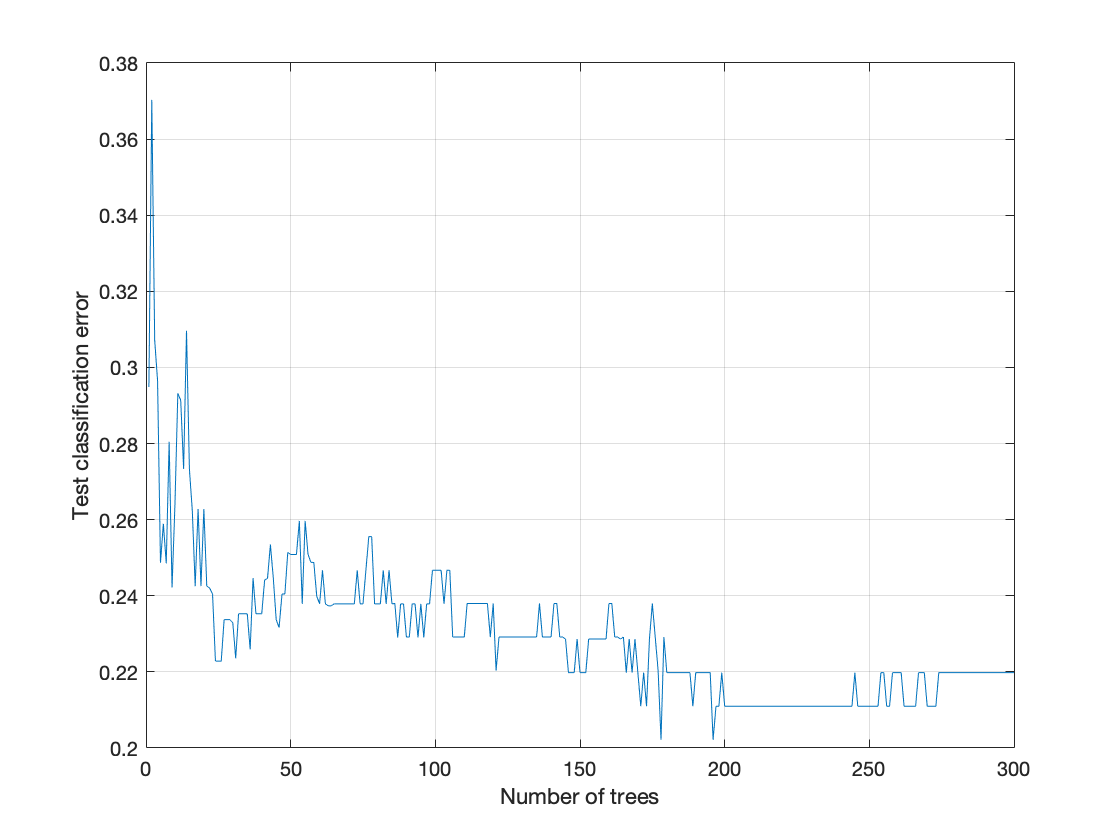

% Plot misclassification/loss against the number of trees in the ensemble.
figure;
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));
grid on;
xlabel('Number of trees');
ylabel('Test classification error');

The ensemble reaches the minimum error between 130-134 trees with an error of ~26%

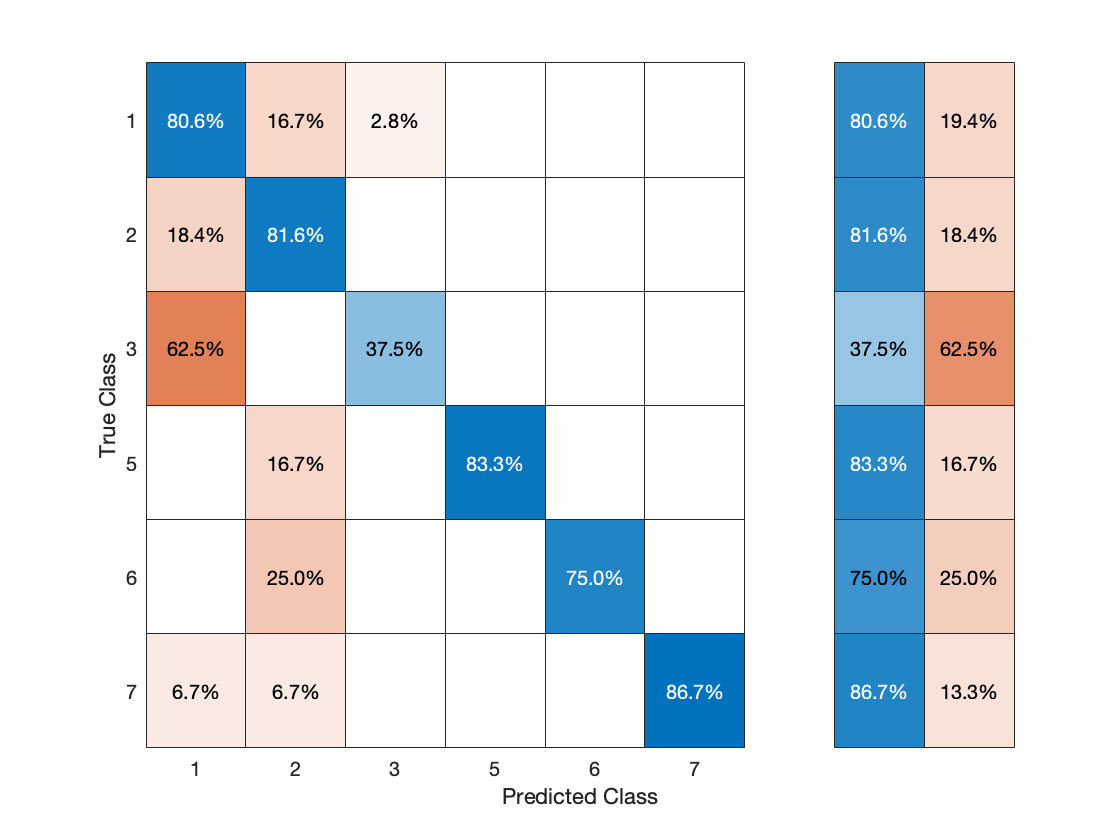

% confusion matrix
Yfit = predict(rf_mdl, test_X);
confusionchart(test_Y,Yfit,'Normalization','row-normalized','RowSummary','row-normalized')


% loss
rf_loss = loss(rf_mdl, test_X, test_Y)

rf_loss = 0.2198

**Cross Validation Error**

Generate a five-fold cross-validated ensemble.

% Perform cross-validation
rf_cv= crossval(rf_mdl, 'KFold', 5);

Examine the cross-validation loss as a function of the number of trees in the ensemble.

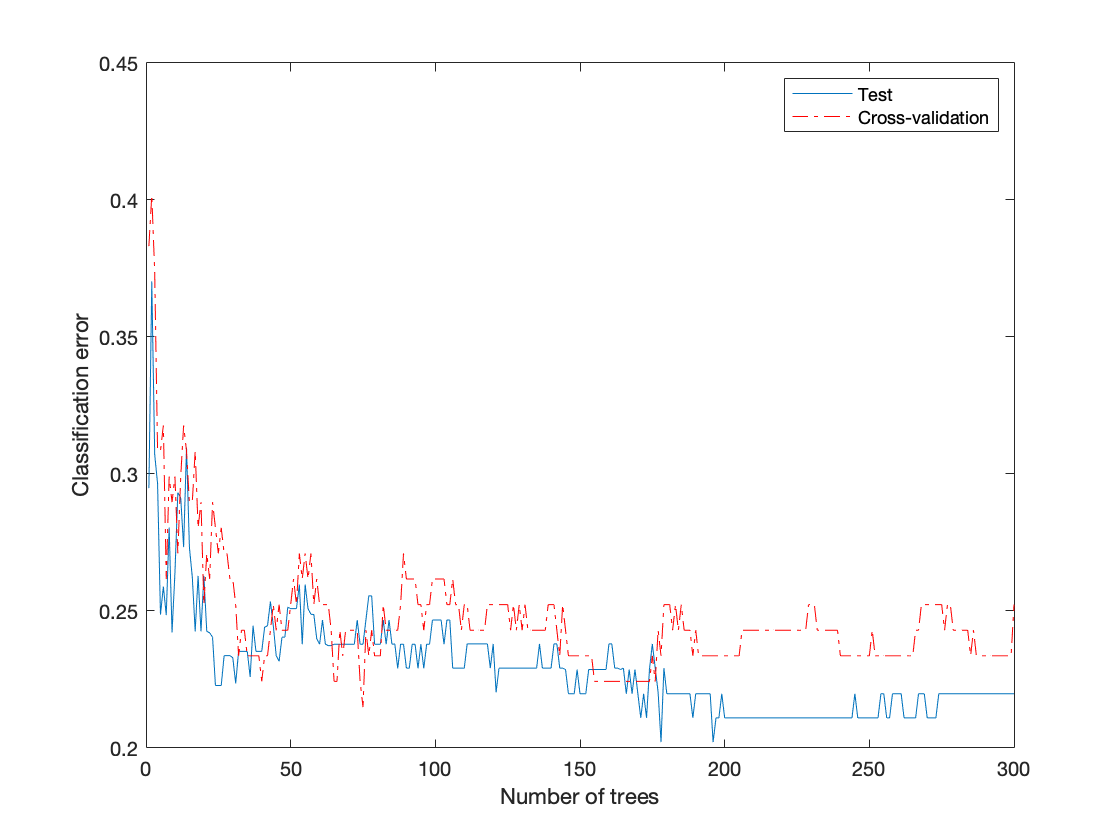

figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Location','NE')

Cross validating gives comparable estimates to those of the independent set.

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(rf_cv)

validationPredictions =      1
     2
     1
     1
     1
     2
     1
     1
     1
     2


validationScores =     0.4767    0.2133    0.3033         0    0.0033    0.0033
    0.4767    0.4800    0.0433         0         0         0
    0.7167    0.2633    0.0200         0         0         0
    0.7833    0.2033    0.0133         0         0         0
    0.6667    0.2500    0.0833         0         0         0
    0.0433    0.9167    0.0400         0         0         0
    0.7500    0.2000    0.0467    0.0033         0         0
    0.9100    0.0733    0.0100         0         0    0.0067
    0.3867    0.1200    0.3367         0    0.0567    0.1000
    0.1633    0.6167    0.2100    0.0100         0         0



% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(rf_cv, 'LossFun', 'ClassifError')

validationAccuracy = 0.7477

**Out-of-Bag Error**

Generate the loss curve for out-of-bag estimates, and plot it along with the other curves.

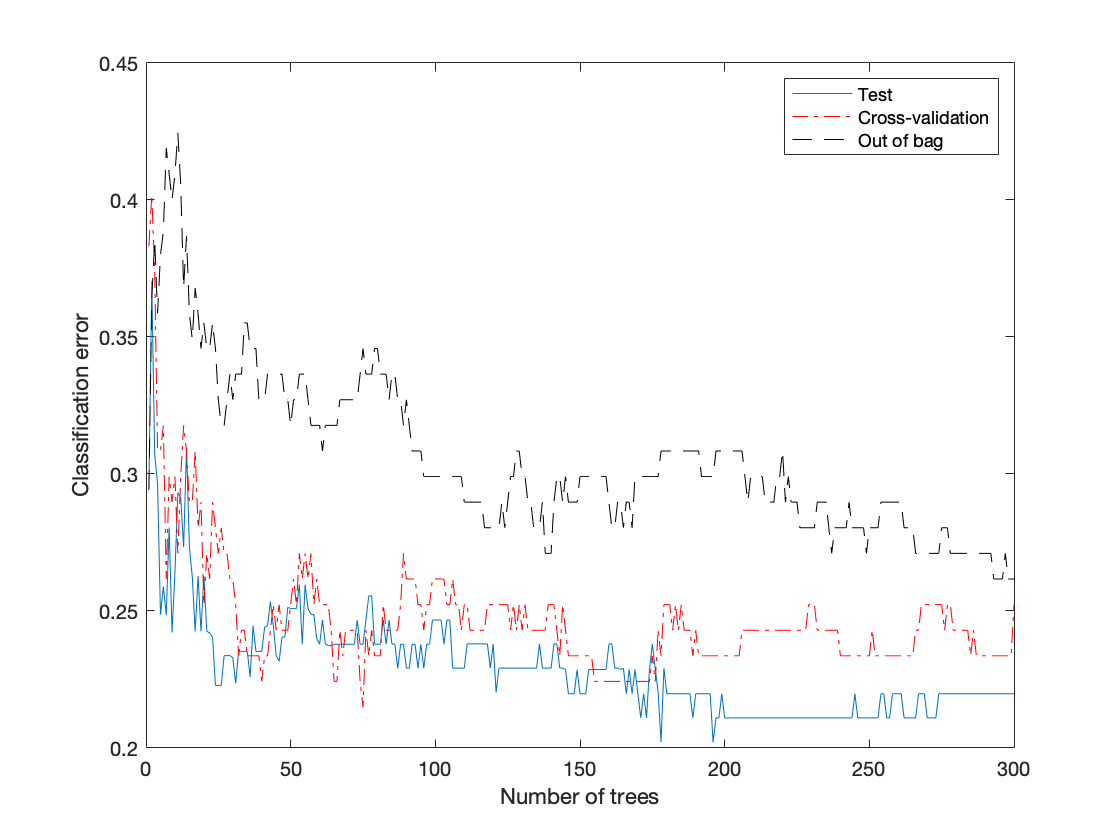

% out of bag estimates
figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
plot(oobLoss(rf_mdl,'mode','cumulative'),'k--')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Out of bag','Location','NE')

#### iii. Optimisation

The curve contains a minimum cross-validated misclassification rate occurring at the optimal number of trees in the ensemble.

[minErr, minErridx] = min(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));

fprintf('\nMinimum classification error = %0.5f',minErr)


Minimum classification error = 0.20215

fprintf('\nOptimal Num. Trees = %d',minErridx);


Optimal Num. Trees = 178

re-train the model with those values

#### iv. Final Preditions

Create a predictive random forest based on the optimal hyperparameters and the entire training set.

tFinal = templateTree('MaxNumSplits',N, 'Reproducible', true);
rf_Final = fitcensemble(train_X,train_Y,'Method', 'Bag', 'NumLearningCycles',minErridx,...
    'Learners',tFinal);

make predictions with the new model

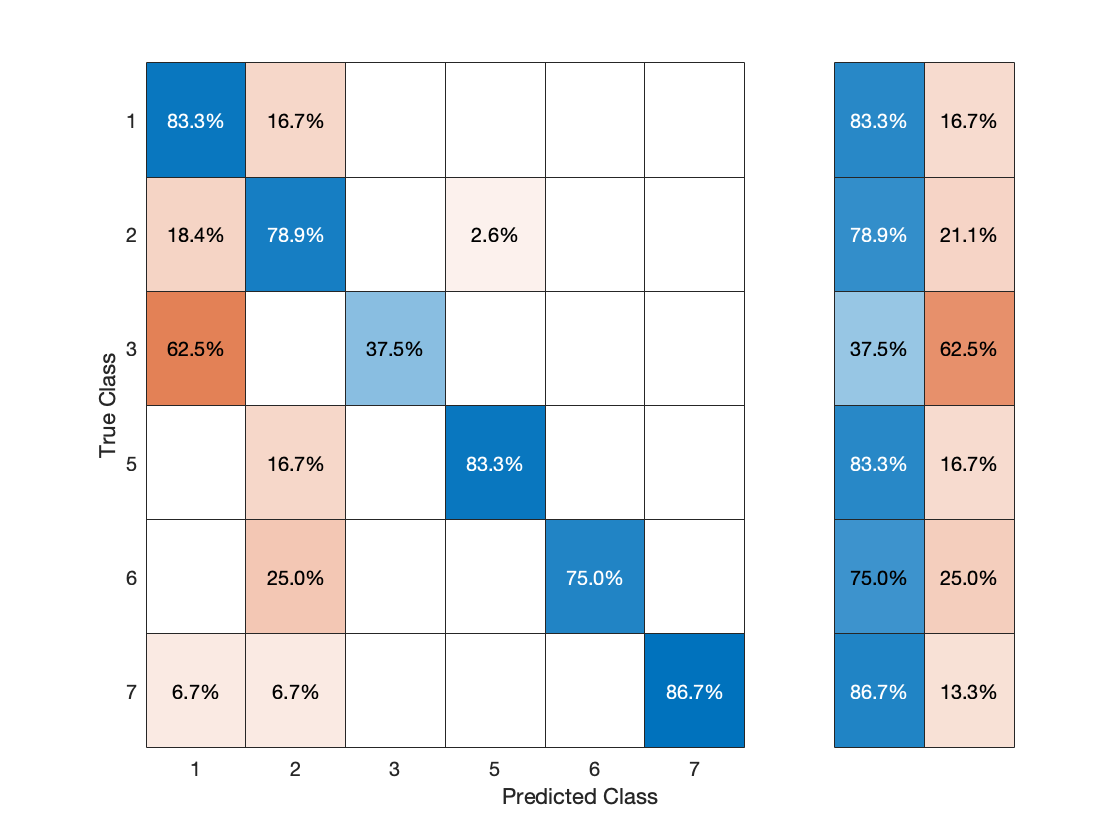

% confusion matrix
Yfit_final = predict(rf_Final, test_X);
confusionchart(test_Y,Yfit_final,'Normalization','row-normalized','RowSummary','row-normalized')

% loss

rf_loss_final = loss(rf_mdl, test_X, test_Y)

### C. Decision Trees

#### **i. Model Training**

dt_mdl = fitctree(train_X, train_Y);

rf_loss_final = 0.2198